## divide train set and test set

data = X_nir_totaled(1:600,:);
label = y_nir;
format short g

rng(1); % For reproducibility
cvp = cvpartition(y_nir, 'Holdout', 0.3)

cvp = 留出交叉验证数据分区
   NumObservations: 600
       NumTestSets: 1
         TrainSize: 420
          TestSize: 180

## modified cars 

%vsels = [];
%RMSECVs = [];

testnums = [100];
vsel_best_m_nir = zeros(length(effwavelengths), length(testnums));
RMSECV_mins = zeros(1, length(testnums));
minRMSECVs = [];
num_vsel_cars = [];

tic
for cc = 1:length(testnums)

    iternum = testnums(cc);
    RMSECV_min = 1;
    vsel_best_nir = 1:length(effwavelengths);

    for i = 1:iternum
        Cars = feature_cars(data(training(cvp), :),...
            label(training(cvp)), 7, 5, 'center', 50, i);

        vsel_incre = Cars.vsel;
        minRMSECV_incre = Cars.minRMSECV;
        %RMSECV_incre = Cars.RMSECV;

        %vsels = [vsels, vsel_incre];
        %RMSECVs = [RMSECVs, RMSECV_incre];
        minRMSECVs = [minRMSECVs, minRMSECV_incre];
        num_vsel_cars = [num_vsel_cars, length(vsel_incre)];

        if length(vsel_incre) < length(vsel_best_nir)
            if  minRMSECV_incre <= RMSECV_min+0.3

                RMSECV_min = minRMSECV_incre;
                vsel_best_nir = vsel_incre;

            end
        end
    end

    fprintf('The %d try finished.\n', iternum)
    fprintf('RMSECV_min = %.6f \n', RMSECV_min)
    vsel_best_nir

    RMSECV_mins(cc) = RMSECV_min;
    vsel_best_00 = [vsel_best_nir, zeros(1, length(effwavelengths)-length(vsel_best_nir))];
    vsel_best_m_nir(:, cc) = vsel_best_00;

end

The 100 try finished.


RMSECV_min = 0.359277 


vsel_best_nir =      2     7    12    45    96    98   205   221   233   234   235   236   248   249   250   263   264   279   280   295


toc

历时 32.195652 秒。


## vsel_best

data = X_nir_totaled(1:600,:);
label = y_nir;

vsel_best_nir = vsel_best_m_nir(1:20);
train_data  = data(training(cvp), vsel_best_nir);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_best_nir);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

*
optimization finished, #iter = 65
nu = 0.013281
obj = -6.061475, rho = -0.184585
nSV = 20, nBSV = 0
.*.*
optimization finished, #iter = 454
nu = 0.312308
obj = -186.263785, rho = -0.503885
nSV = 73, nBSV = 38
*.*
optimization finished, #iter = 244
nu = 0.136322
obj = -71.997754, rho = 0.101564
nSV = 49, nBSV = 12
*
optimization finished, #iter = 35
nu = 0.015708
obj = -7.168881, rho = 0.084368
nSV = 17, nBSV = 0
*
optimization finished, #iter = 98
nu = 0.050848
obj = -28.889860, rho = 0.250029
nSV = 28, nBSV = 3
*
optimization finished, #iter = 138
nu = 0.115396
obj = -68.726252, rho = 0.343932
nSV = 35, nBSV = 13
Total nSV = 137
*
optimization finished, #iter = 61
nu = 0.011546
obj = -5.269998, rho = -0.201825
nSV = 20, nBSV = 0
.*.*
optimization finished, #iter = 402
nu = 0.354374
obj = -217.950216, rho = -0.574365
nSV = 76, nBSV = 45
*.*
optimization finished, #iter = 270
nu = 0.124745
obj = -67.367595, rho = 0.160857
nSV = 48, nBSV = 12
*
optimization finished, #iter = 67
nu = 0.

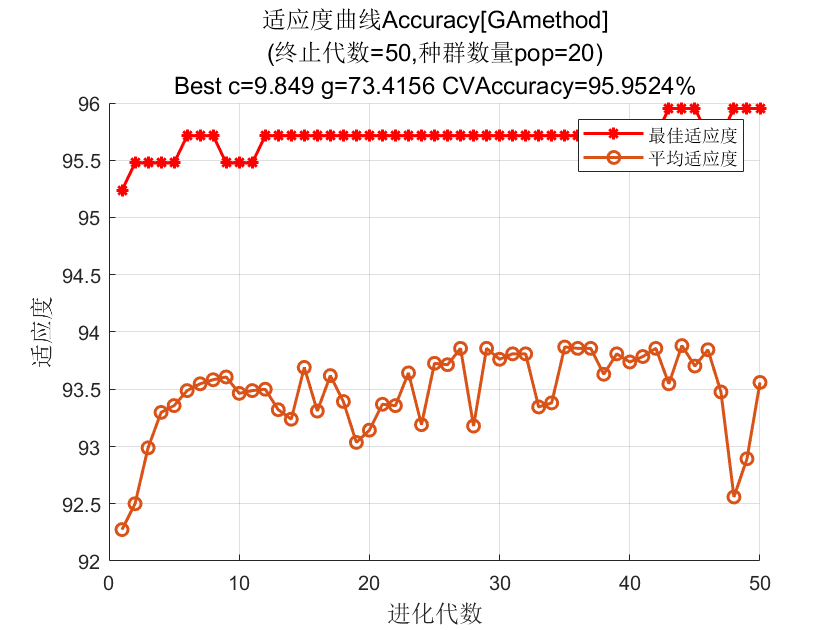

tic
[~, bestc, bestg] = gaSVMcgForClass(train_label, train_data);

toc

历时 27.538669 秒。


% vsel_best
s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 73
nu = 0.006479
obj = -6.700057, rho = -0.163565
nSV = 33, nBSV = 0
.*.*
optimization finished, #iter = 479
nu = 0.221963
obj = -279.410696, rho = -0.379366
nSV = 73, nBSV = 27
.*
optimization finished, #iter = 351
nu = 0.065734
obj = -72.270851, rho = 0.148643
nSV = 54, nBSV = 4
*
optimization finished, #iter = 71
nu = 0.007146
obj = -7.389838, rho = 0.088821
nSV = 26, nBSV = 0
*
optimization finished, #iter = 126
nu = 0.034383
obj = -39.760085, rho = 0.276780
nSV = 35, nBSV = 3
*.*
optimization finished, #iter = 243
nu = 0.080010
obj = -94.989962, rho = 0.338705
nSV = 45, nBSV = 8
Total nSV = 160



[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 99.7619% (419/420) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 92.7778% (167/180) (classification)


valid_data = X_nir_totaled(601:end,vsel_best_nir);
valid_label = y_valid;

[~, valid_acc, ~]...
    = libsvmpredict(valid_label, valid_data, model);

Accuracy = 20% (32/160) (classification)
